# Tissue Sense classification

MathWorks Consulting 2022

## Round 1 

## Import Dataset

tic

x=1;
sensitivity=table();
specificity=table();
accuracytb=table();
precision=table();

for integra = 1%[0.5 0.85 1]
distanceRange = "ZeroToFive";
%integra =0.1;
% Add all folders to path
addpath(genpath(pwd));

dslocation = fullfile(pwd, "data", "TRL5-Xenon-AB-OFF/04-01/");
%dataObj = load(fullfile(dslocation, "data1.mat"));
%dataTrain = dataObj.dataTrain;
%dataTest = dataObj.dataTest;
darkReference = fullfile(pwd, "data", "/Dark/1_S3_Alpha1_DARK AB OFF.xlsx")
datadescription = 'XenonABOFF-5Avg'; 
[dataAll, dataSummary] = ops.import.readCSV( dslocation, darkReference, "IncludeSubfolders", true);


%dataAll.Response = dataAll.TargetType;
datestr(now, 'dd/mm/yy-HH:MM')

head(dataAll)





darkReference = "D:\TRL5-TissueSense-script\data\Dark\1_S3_Alpha1_DARK AB OFF.xlsx"

ans = '10/01/25-15:54'

    Feature 1    Feature 2    Feature 3    Feature 4    Feature 5    Feature 6    Feature 7    Feature 8    Feature 9    Feature 10    Feature 11    Feature 12    Feature 13    Feature 14    Feature 15    Feature 16    Feature 17    Feature 18    Feature 19    Feature 20    Feature 21    Feature 22    Feature 23    Feature 24    Feature 25    Feature 26    Feature 27    Feature 28    Feature 29    Feature 30    Feature 31    Feature 32    Featu

% Set the response variable
dataAll.Response = dataAll.TargetType;

% Filter out any data that is not being used for this run
% data(data.TargetType=="Tissue-Ureter",:) = [];
% data(data.TargetType=="Tissue-Calyx",:) = [];

% Specify integration time used. Comment line out if you want to use all
% integration times. 

stringint=num2str(integra);
dataAll(dataAll.IntegrationTimeUsed~=stringint,:) = [];
data1 = dataAll;
%currentFilter = data.ResponseRegression >= -4 & data.ResponseRegression < 0
currentFilter = data1.Position >= 0 & data1.Position < 6;
data = data1(currentFilter, :);



data.Response(ismember(data.Response, ["Access Sheath", "No Target",...
   "Endoscope", "COM","UA", "BEGO", "Guidewire", "CHPD", "CYS", "MAGPH", "MAPH"])) = "Non-Tissue";

%dataTrain.Response(ismember(dataTrain.Response, ["COM","UA"])) = "Stone";

%dataTest.Response(ismember(dataTest.Response, ["Access Sheath 13/15"...
    %"Endoscope", "Tissue-Calyx", "Tissue-Ureter", "BEGO"])) = "Non-Stone";

data.Response(ismember(data.Response, ["Tissue-Calyx", "Tissue-Ureter"])) = "Tissue";

%stringint=num2str(integra);
%data(data.IntegrationTimeUsed~=stringint,:) = [];


#### Partition dataset

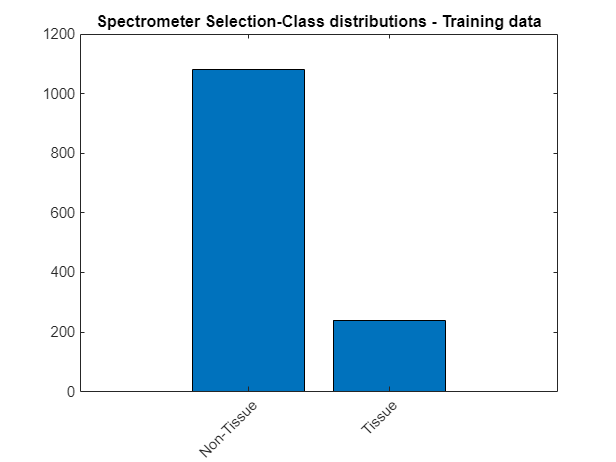

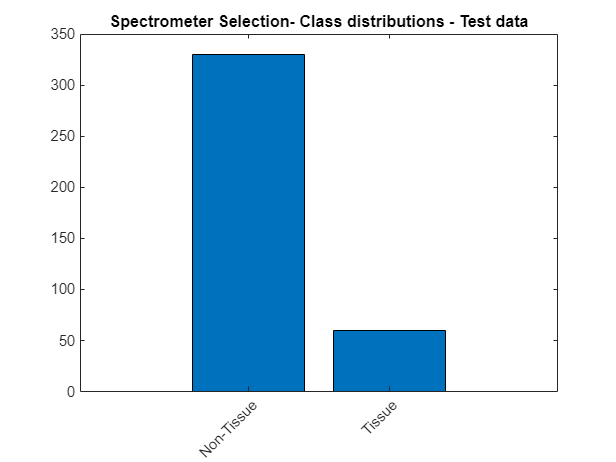

rng(0);
% trainIdx = contains(data.FileName, "TDP-02");
% testIdx = contains(data.FileName, "TDP-02");
% 
% dataTrain = data(trainIdx, :);
% dataTest = data(testIdx, :);

% Split dataset for training and testing
trainPercent = 80; % percentage to use for training
%splitn = splitlabels(data.Response, trainPercent/100, 'randomized');

splitn = ops.partitionDataBasedonFilenames(data, trainPercent);
dataTrain = data(splitn{1},:);
dataTest  = data(splitn{2}, :);
dataTest1 = dataTest;
%partObj = cvpartition(height(data), 'HoldOut', testPercent/100);
%dataTrain = data(partObj.training,:);
%dataTest  = data(partObj.test, :);

#### Visualize class distributions

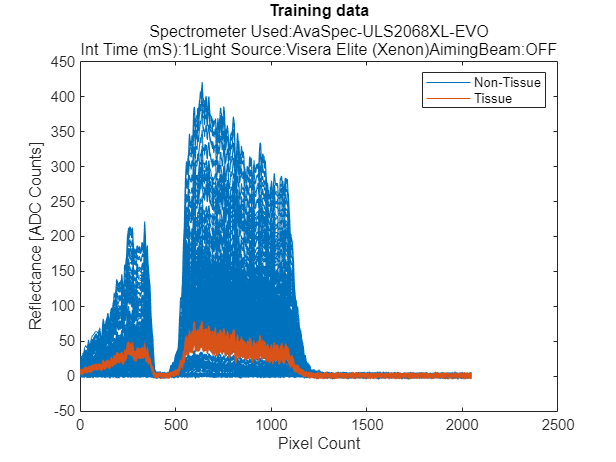

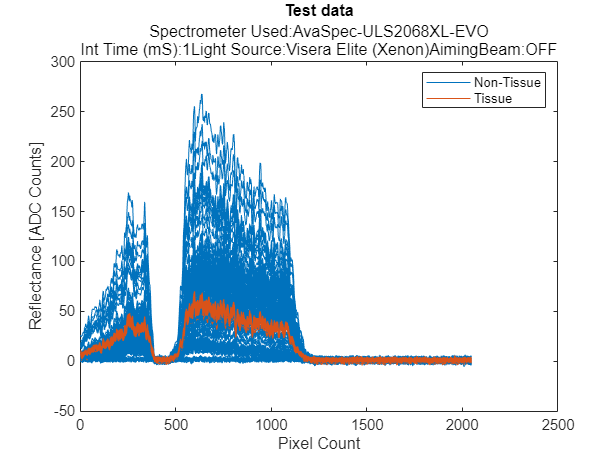

summary = groupsummary(dataTrain, "Response");
figure("Color", "W")
ax = gca;
bar( ax, summary.GroupCount );
ax.XTick = 1:height(summary);
ax.XTickLabel = summary.Response;
ax.XTickLabelRotation = 45;
title(ax, "Spectrometer Selection-Class distributions - Training data" )
summary = groupsummary(dataTest, "Response");

figure("Color", "W")
ax = gca;
bar( ax, summary.GroupCount );
ax.XTick = 1:height(summary);
ax.XTickLabel = summary.Response;
ax.XTickLabelRotation = 45;
title(ax, "Spectrometer Selection- Class distributions - Test data" )

## Visualize raw signal waveforms

### Naming Format for Date and Time / File save Location 

formatOut = 'yyyymmddTHHMMSS';
CurrentDate=datestr(now,formatOut);
savefigloc='C:\Users\bhavana.maradani\Desktop\temp';

Training Data Chart 

f5 =   Figure (7) with properties:

      Number: 7
        Name: ''
       Color: [1 1 1]
    Position: [680 458 560 420]
       Units: 'pixels'

  Show all properties


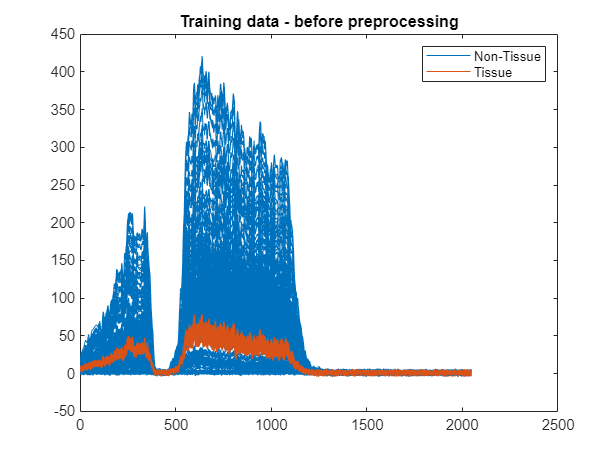

f6 =   Figure (9) with properties:

      Number: 9
        Name: ''
       Color: [1 1 1]
    Position: [680 458 560 420]
       Units: 'pixels'

  Show all properties


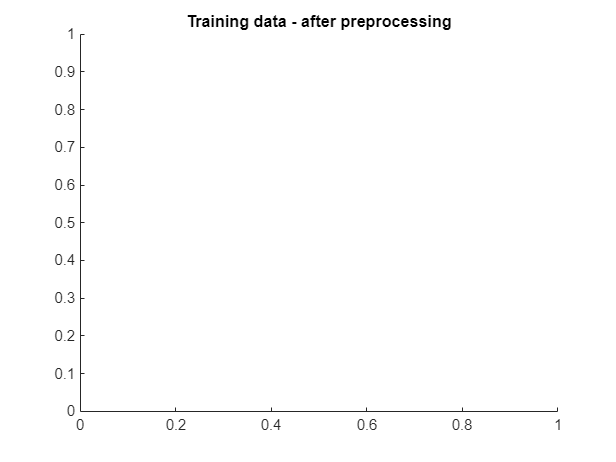

f7 =   Figure (10) with properties:

      Number: 10
        Name: ''
       Color: [1 1 1]
    Position: [680 458 560 420]
       Units: 'pixels'

  Show all properties


f3=figure("Color", "W");
ops.util.plotSummarySignals(dataTrain, "Response");
title("Training data");
Description = 'Training Data Waveform View';
spec= strcat('Spectrometer Used:',data.SpectrometerUsed(1));
sub = strcat('Int Time (mS): ',data.IntegrationTimeUsed(1),'Light Source:',data.LightSource(1),'AimingBeam:',data.AimingBeam(1));
text={spec,sub};
subtitle(text);
xlabel('Pixel Count') ;
ylabel('Reflectance [ADC Counts]') ;
savenamefig=strcat(savefigloc,Description,CurrentDate,'.fig');
savenamejpg=strcat(savefigloc,Description,CurrentDate,'.jpg');
% saveas(f3,savenamefig);
% saveas(f3,savenamejpg);

Test Data Chart 

f4=figure("Color", "W");
ops.util.plotSummarySignals(dataTest, "Response");

ans = 1×4 string array
    "Response"    "Normalization"    "FeatureExtraction"    "FeatureSelection"


ans = 7×1 string array
    "Learners"
    "OptimizeHyperparameters"
    "HyperparameterOptimizationOptions"
    "CrossValidation"
    "KFold"
    "Holdout"
    "Seed"


title("Test data");
Description = 'Test Data Waveform View';
spec= strcat('Spectrometer Used:',data.SpectrometerUsed(1));
sub = strcat('Int Time (mS): ',data.IntegrationTimeUsed(1),'Light Source:',data.LightSource(1),'AimingBeam:',data.AimingBeam(1));
text={spec,sub};
subtitle(text);
xlabel('Pixel Count') ;
ylabel('Reflectance [ADC Counts]') ;
savenamefig=strcat(savefigloc,Description,CurrentDate,'.fig');
savenamejpg=strcat(savefigloc,Description,CurrentDate,'.jpg');
% saveas(f4,savenamefig);
% saveas(f4,savenamejpg);

#### Data preparation

% keep only predictor names and response in the data
predictorNames = string(dataTrain.Properties.VariableNames(...
                contains(dataTrain.Properties.VariableNames, "Feature")))';

dataTrain = dataTrain(:,[predictorNames; "Response"]);
dataTest = dataTest(:,[predictorNames; "Response"]);

## Prototype data preparation pipeline

Before applying machine learning, we'll write a function that applies a series of sequential processsing steps on the data. In this case, we'll remove contant variables, since they will not contribute information to the problem, and in fact may cause certain algorithms to fail. We'll use zscore normalization to scale each feature column, as mangitudes of various sensors value differ by orders of magnitude.

A Correlation matrix expresses patterns/relationships in the data and lists the features used in training. 

%Preview pipeline
resultOfPipeline = basePipelineTrain( dataTrain, ...
    "Response", "Response", ...
    "Normalization", "zscore", ...

ans = 3×5 table
              Normalization    FeatureSelection    FeatureExtraction    KFold                             Learners                          
              _____________    ________________    _________________    _____    ___________________________________________________________

    Trial1      "zscore"          "none"                "none"            5      "tree"    "ecoc"    "discr"    "knn"    "svm"    "ensemble"
    Trial2      "zscore"          "fscchi2"             "none"            5      "tree"    "ecoc"    "discr"    "knn"    "svm"    "ensemble"
    Trial3      "zscore"          "pca"                 "none"            5      "tree"    "ecoc"    "discr"    "knn"    "svm"    "ensemble"


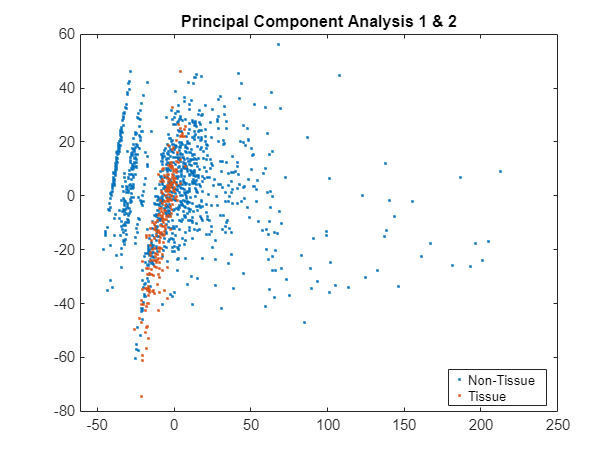

Running: tree
Running: discr
Running: knn
Running: svm
Running: ensemble
Running: ecoc
Running: tree
Running: discr
Running: knn
Running: svm
Running: ensemble


    "FeatureExtraction","none", ...
    "FeatureSelection", "pca");

featurenames = resultOfPipeline.Properties.CustomProperties.Features;


%Visualize 
f5=figure("Color", "W")
ops.util.plotSummarySignals(dataTrain, "Response")
title("Training data - before preprocessing")

f6=figure("Color", "W")
%ops.util.plotSummarySignals(resultOfPipeline, "Response", "predictorNames", featurenames);
title("Training data - after preprocessing")



f7=figure("Color", "W")
gscatter(resultOfPipeline{:,1}, resultOfPipeline{:,2}, resultOfPipeline.Response)
Description = 'Principal Component Analysis 1 & 2';
title(Description);
savenamefig=strcat(savefigloc,Description,CurrentDate,'.fig');
savenamejpg=strcat(savefigloc,Description,CurrentDate,'.jpg');
saveas(f7,savenamefig);
saveas(f7,savenamejpg);

## Configure experiment parameters

Before configuring the experiment trials, we'll preview the variables available for experimentation. These are grouped into two sets: data preparation parameters and model parameters. Data preparation refers to the processing we apply to the data to prepare it for the models. This commonly includes feature engineering, scaling, etc.. (see above). Model parameters include settings we define for the ml algorithms. These parameters commonly include validation decisions (e.g. KFold), list of models/learners we want to include, as well as decisions on whether we will optimize hyperparameters during training. 

optimizeParameter.listPipelineOptions("basePipelineTrain")
optimizeParameter.listModelParameters( "Classification" )

In this example, we'll configure the experiment for a single trial to develop an initial picture of model performance. We will not optimize hyperparameters, but we may elect to do so later. 

dataParameters = optimizeParameter.empty(0,1);
modelParameters = optimizeParameter.empty(0,1);

% Data parameters 
% Data parameters 

dataParameters(1) = optimizeParameter.new(...
    "Name", "Normalization", ...
    "Range", ["zscore"], ...
    "Type", "Discrete");

dataParameters(2) = optimizeParameter.new(...
    "Name", "FeatureSelection", ...
    "Range", ["none", "fscchi2", "pca"], ...
    "Type", "Set");

dataParameters(3) = optimizeParameter.new(...
    "Name", "FeatureExtraction", ...
    "Range", ["none"], ...
    "Type", "Set");

% % Model Parameters
% modelParameters(1) = optimizeParameter.new(...
%     "Name", "KFold", ...
%     "Range", 5,...
%     "Type", "Discrete");
% 
% modelParameters(2) = optimizeParameter.new(...
%     "Name", "Learners", ...
%     "Range", {["tree"]}, ...
%     "Type", "Set");

% dataParameters(1) = optimizeParameter.new(...
%     "Name", "Normalization", ...
%     "Range", ["none", "zscore", "range"], ...
%     "Type", "Discrete");
% 
% dataParameters(2) = optimizeParameter.new(...
%     "Name", "FeatureSelection", ...
%     "Range", ["none", "fscchi2", "pca"], ...
%     "Type", "Set");
% 
% dataParameters(3) = optimizeParameter.new(...
%     "Name", "FeatureExtraction", ...
%     "Range", ["none", "descriptivestatistics"], ...
%     "Type", "Set");

% Model Parameters
modelParameters(1) = optimizeParameter.new(...
    "Name", "KFold", ...
    "Range", 5,...
    "Type", "Discrete");

modelParameters(2) = optimizeParameter.new(...
    "Name", "Learners", ...
    "Range", {["tree", "ecoc", "discr",  "knn",  "svm",...
    "ensemble"]}, ...
    "Type", "Set");
%}
%     "Range", {["tree", "discr",  "knn",  "svm", ...
%     "ensemble", "ecoc", "linear", "kernel", "nnet"]},...

## Create classification experiment w/ gridsearch

In this section, we'll create the experiment, first by specifing the dataset and a model selection (autoML will use all available classification methods), then by specifying the DataFcn, which refers to the data preparation pipeline we prototyped in earlier sections. We'll need to provide it as an anonymous function, since the experimental framework will input multiple combinations of parameters during the trials.The syntax is: 

- @(data, settings)pipelinefunction(data, settings{:})

Finally, we'll specify the optional data and model configurations defined in the earlier section. In this case, the parameters are all scalar and there will be a single trial, otherwise the experiment would consist of a series of trials swept using gridsearch. 

session = experiment.Classification( ...
    "Data", dataTrain, ...
    "Model", "automl", ...
    "DataFcn", @(x, settings)basePipelineTrain(x, settings{:}), ...
    "DataConfiguration", dataParameters, ...
    "ModelConfiguration", modelParameters, ...
    "Search", "gridsearch", ...
    "NumGridDivisions", 2 ...
    );

## Prepare

In this section, we validate our configuration, build, and preview our trials. 

session.validate()
session.build()
session.preview()

## Train session

Automl will run all available classification methods in sequence. 

 session.run()

## Evaluate

Assess model performance using evaluation metrics calculated for each model. 

evalT = session.describe();
evalT = [evalT(:,1:9) evalT(:,14) evalT(:,10:13) evalT(:,15:18)]

## Visualize

figure("Color", "W")
tiledlayout("flow")
nexttile()
session.plotmetric( "Metric", "errorOnCV" );
nexttile()
session.plotmetric( "Metric", "errorOnTest" );

The confusion chart enables us to visualize model performance on a per-class basis. 

% figure("Color", "W"), session.confusionchart()

## Model selection

Sort the results according to an evaluation metric. In this example, we'll use cross validation error. 

sessionResults = session.sort("Metric","errorOnTest")

Select a model from the experiment trials based on the evaluation criteria. Utlimately the selected models will be used for prediction in production.

iD = sessionResults.Item(1);
[results, info] = session.select(iD, "Metadata", true)

Save resulting model and associated metadata to disk.

% trialDir = fullfile(pwd, "results");
% 
% fileName = strcat('model_', string(integra), datadescription, distanceRange,datestr(now,'mm_dd_yyyy_HH_MM'), '.mat');
% save(iD, fileName, trialDir);
% isSave = true;
% if isSave
%     [statusOk, fileName] = session.save( iD, "Metadata", true, ...
%         "WriteDirectory", trialDir);
% end

trialDir = fullfile(pwd, "results\DemoModels");
%fname = strcat('model_', string(integra), datadescription, distanceRange,datestr(now,'mm_dd_yyyy_HH_MM'), '.mat');
%fname = sprintf('model_%d%s%s%s.mat', integra, datadescription, distanceRange,datestr(now,'mm_dd_yyyy_HH_MM'));
%save(fname, "model1", "model2", "-v7.3")
new_filename = sprintf('TRL5-TS-UnNorm_%s%s%s%s.mat', string(integra), datadescription, distanceRange,datestr(now,'mm_dd_yyyy_HH_MM'));
new_file = fullfile(pwd,"results\DemoModels", new_filename);
isSave = true;
if isSave
    [statusOk, fileName] = session.save( iD, "Metadata", true, ...
        "WriteDirectory", trialDir);
end
old_file = fullfile(pwd,"results\DemoModels", fileName);
movefile(old_file, new_file);

## Inference

In order to inference on new data, we will:

- Load the saved model and associated metadata (for example, pipeline settings) from disk

- Pass the model, pipeline settings, and new data through the prediction pipeline

- Calculate accuracy and visualize confusion matrix

% Change this to filename generated from previous step
filePath = new_file;

result = predictFcn(filePath, dataTest);

accuracy = sum(result.("Response") == result.Prediction) / numel(result.("Response"));

f8=figure()
cm=viz.confusionchart( result, "Response", "Prediction", ...
    "Title", "Test Data Accuracy = " + 100*accuracy + "%   -"+ sub, ...
    "Normalization", "row-normalized", ...
    "RowSummary","row-normalized","ColumnSummary","column-normalized");
Description = 'Confusion Chart';
savenamefig=strcat(savefigloc,Description,CurrentDate,'.fig');
savenamejpg=strcat(savefigloc,Description,CurrentDate,'.jpg');
f8.Position = [10,10,1000,700];
% saveas(f8,savenamefig);
% saveas(f8,savenamejpg);

## Display Score Results 

Confidence= result.Scores


beep on
beep

matrix=cm.NormalizedValues;
labels=string(cm.ClassLabels);
statsmatix= statsOfMeasure(matrix,1);

if x==1  

sensitivity{x,:}= statsmatix.classes(6,:);
specificity{x,:}= statsmatix.classes(7,:);
sensitivity.Properties.VariableNames =labels;
specificity.Properties.VariableNames =labels;

else 

sensitivity{x,:}= statsmatix.classes(6,:);
specificity{x,:}= statsmatix.classes(7,:);
sensitivity
specificity
end 
x=x+1;
end

datestr(now, 'dd/mm/yy-HH:MM')
sensitivity
specificity


%{

precision{x,:}= statsmatix.classes(5,:) ;
accuracytb{x,:}= statsmatix.classes(8,:) ;
sensitivity{x,:}= statsmatix.classes(6,:);
specificity{x,:}= statsmatix.classes(7,:) ;

tstp = matrix (5,5) + matrix (6,6)+ matrix (6,5) + matrix (5,6);
tsfp = sum(matrix(:,5)) + sum(matrix(:,6)) - tstp;
tsfn = sum(matrix(5,:)) + sum(matrix(6,:)) - tstp;
tstn=sum(sum(matrix))-(tstp+tsfp+tsfn);

prec=tstp./(tstp+tsfp);
sens=tstp./(tstp+tsfn);
spec=tstn./(tstn+tsfp);
acc=sum(tstp)./sum(sum(matrix));

precision{x,7} = prec;
accuracytb{x,7}= acc;
sensitivity{x,7}= sens;
specificity{x,7}= spec;


precision.Properties.VariableNames =[labels];
accuracytb.Properties.VariableNames = [labels];
sensitivity.Properties.VariableNames = [labels];
specificity.Properties.VariableNames = [labels];

x = x + 1;

end
sensidata = sensitivity(:,[3 7 5 6 2 1 4])
specidata= specificity(:,[3 7 5 6 2 1 4])
precidata = precision(:,[3 7 5 6 2 1 4])
accudata= accuracytb(:,[3 7 5 6 2 1 4])
%}
toc